# **Md Toufique Hasan**

# **Student Number: 151129267**

# **Exercise date: 16.03.2023**

# **Machine learning algorithms: exercise 1**

#### Answer 1

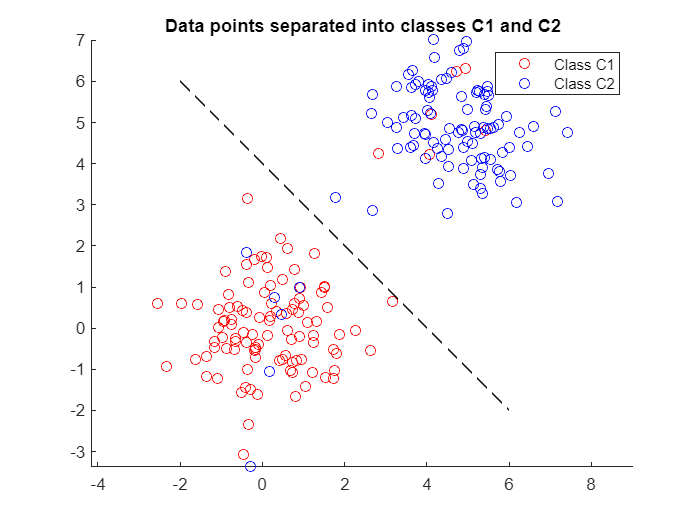

% Load data from the data.txt file
data = load(['D:\TUNI\Courses\Period-4\DATA.ML.210 [Machine Learning Algorithms]' ...
    '\Exercises 1\data.txt']);

% Separate the data into class C1 and class C2
C1 = data(1:100, :);
C2 = data(101:200, :);

% Define the two points that define the line l
p1 = [-2, 6];
p2 = [6, -2];

% Calculate the slope of the line l
m = (p2(2) - p1(2)) / (p2(1) - p1(1));

% Calculate the unit weight vector w that is perpendicular to the line l
w = [-m; 1] / norm([-m; 1]);

% Loop through the 12 unknown points and assign them to C1 or C2
for i = 201:212
point = data(i, :);
if dot(point - p1, w) > 0
C1 = [C1; point];
else
C2 = [C2; point];
end
end

% Plot the results
scatter(C1(:,1), C1(:,2), 'r')
hold on
scatter(C2(:,1), C2(:,2), 'b')
plot([p1(1), p2(1)], [p1(2), p2(2)], 'k--')
axis equal
legend('Class C1', 'Class C2')
title('Data points separated into classes C1 and C2')

#### **Answer: 2**

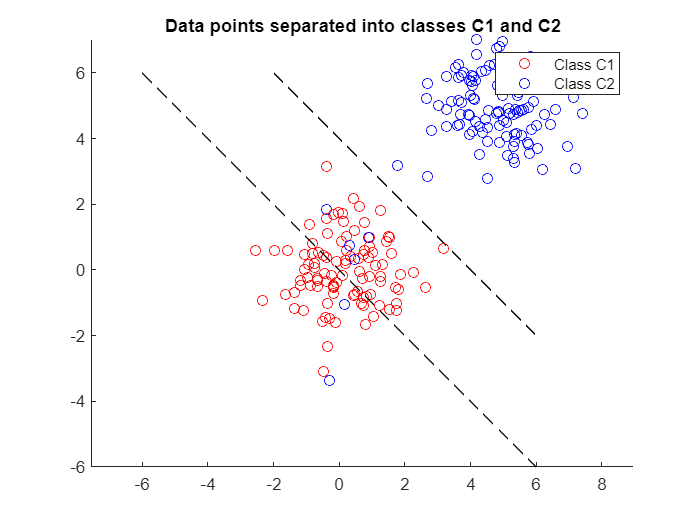

% Separate the data into class C1 and class C2
C1 = data(1:100, :);
C2 = data(101:200, :);

% Define the unit weight vector w that is perpendicular to the line l
w = [-1; 1] / sqrt(2);

% Initialize the threshold t to a large negative value
t = -inf;

% Loop through all the points in class C1 and update the value of t if necessary
for i = 1:size(C1, 1)
x = C1(i, :)';
wTx = w' * x;
if wTx > t
t = wTx;
end
end

% Loop through all the points in class C2 and update the value of t if necessary
for i = 1:size(C2, 1)
x = C2(i, :)';
wTx = w' * x;
if wTx < t
t = wTx;
end
end

% Classify the 12 unknown points in Data.txt
for i = 201:212
x = data(i, :)';
wTx = w' * x;
if wTx < t
C1 = [C1; x'];
else
C2 = [C2; x'];
end
end

% Plot the results
scatter(C1(:,1), C1(:,2), 'r')
hold on
scatter(C2(:,1), C2(:,2), 'b')
plot([-6, 6], [6, -6], 'k--')
axis equal
legend('Class C1', 'Class C2')
title('Data points separated into classes C1 and C2')

#### **Answer: 3**

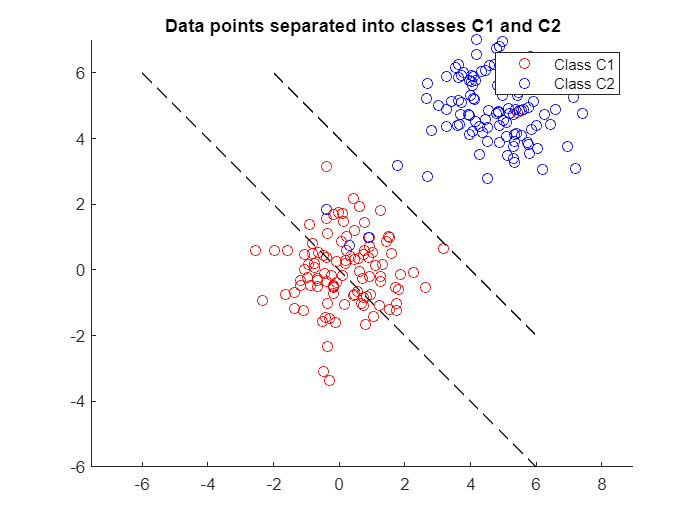

% Separate the data into class C1 and class C2
C1 = data(1:100, :);
C2 = data(101:200, :);

% Define the unit weight vector w that is perpendicular to the line l
w = [-1; 1] / sqrt(2);

% Initialize the signs of wTx to all zeros
signs = zeros(size(data, 1), 1);

% Loop through all the points in class C1 and set the sign of wTx to -1
for i = 1:size(C1, 1)
x = C1(i, :)';
wTx = w' * x;
signs(i) = -1;
end

% Loop through all the points in class C2 and set the sign of wTx to 1
for i = 1:size(C2, 1)
x = C2(i, :)';
wTx = w' * x;
signs(i+100) = 1;
end

% Classify the 12 unknown points in Data.txt
for i = 201:212
x = data(i, :)';
wTx = w' * x;
if wTx >= 0
C2 = [C2; x'];
else
C1 = [C1; x'];
end
end

% Plot the results
scatter(C1(:,1), C1(:,2), 'r')
hold on
scatter(C2(:,1), C2(:,2), 'b')
plot([-6, 6], [6, -6], 'k--')
axis equal
legend('Class C1', 'Class C2')
title('Data points separated into classes C1 and C2')

#### **Answer: 4**

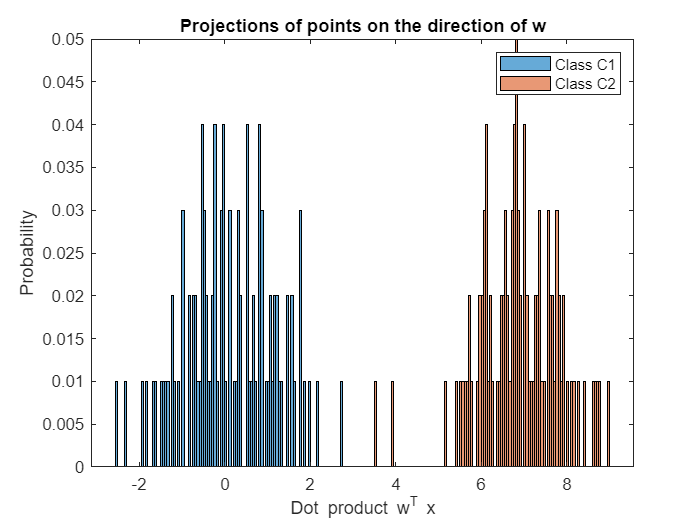

% Extract the points belonging to class C1 and C2
C1 = data(1:100, :);
C2 = data(101:200, :);

% Calculate the unit weight vector w perpendicular to line passing through p1 and p2
p1 = [-2, 6];
p2 = [6, -2];
d = p2 - p1;
v = [-d(2), d(1)];
w = v / norm(v);

% Calculate the dot products of C1 and C2
C1_w_dot_products = w * C1';
C2_w_dot_products = w * C2';
C1_l_dot_products = d * C1';
C2_l_dot_products = d * C2';

% Draw histograms of the projections on the direction of w
figure;
histogram(C1_w_dot_products, 'Normalization', 'probability', 'BinWidth', 0.05);
hold on;
histogram(C2_w_dot_products, 'Normalization', 'probability', 'BinWidth', 0.05);
title('Projections of points on the direction of w');
xlabel('Dot product w^T x');
ylabel('Probability');
legend('Class C1', 'Class C2');

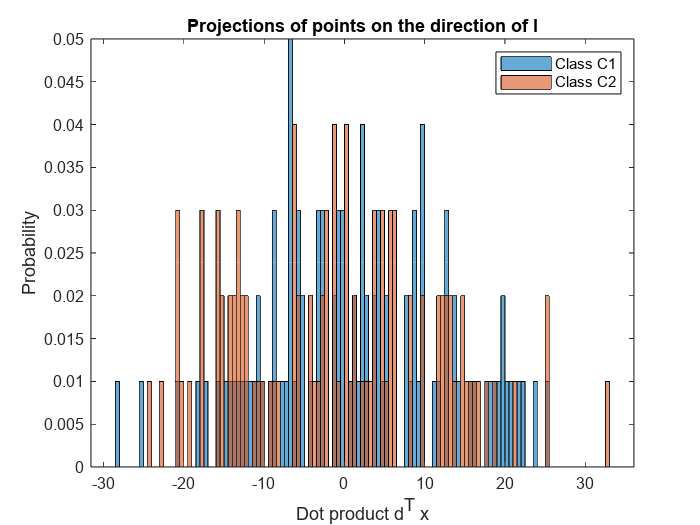

% Draw histograms of the projections on the direction of l
figure;
histogram(C1_l_dot_products, 'Normalization', 'probability', 'BinWidth', 0.5);
hold on;
histogram(C2_l_dot_products, 'Normalization', 'probability', 'BinWidth', 0.5);
title('Projections of points on the direction of l');
xlabel('Dot product d^T x');
ylabel('Probability');
legend('Class C1', 'Class C2');

% Interpret the results
disp("Interpretation of the results:");

Interpretation of the results:


disp("Class C1 has higher projections than class C2");

Class C1 has higher projections than class C2, which means that w separates the two classes well.


disp("The direction of l show a large overlap between the two classes");

The direction of l show a large overlap between the two classes


#### **Answer: 5**

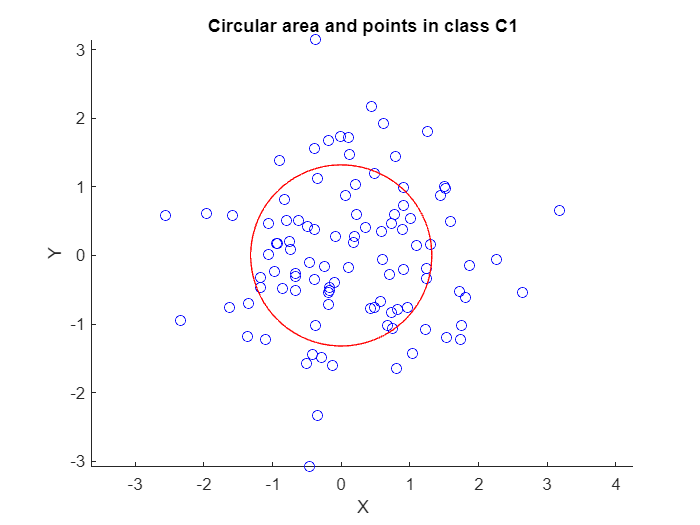

% Extract the points belonging to class C1
C1 = data(1:100, :);

% Calculate the mean distance r from the center point (0,0) to all points in class C1
r = mean(sqrt(C1(:,1).^2 + C1(:,2).^2));

% Define the circular area with radius r and center point (0,0)
theta = linspace(0, 2*pi, 100);
x = r * cos(theta);
y = r * sin(theta);

% Count the number of points in class C1 that fall within this circular area
count = 0;
for i = 1:size(C1, 1)
if norm(C1(i,:)) <= r
count = count + 1;
end
end

% Divide the count by the total number of points in class C1 to obtain the probability
probability = count / size(C1, 1);

% Plot the circular area and the points in class C1
figure;
scatter(C1(:,1), C1(:,2), 'b');
hold on;
plot(x, y, 'r');
axis equal;
title('Circular area and points in class C1');
xlabel('X');
ylabel('Y');

% Print the probability
disp("C1 belongs to the circular area with radius " + r + ...
    " and center point (0,0) is " + probability);

The probability that a point in class C1 belongs to the circular area with radius 1.3195 and center point (0,0) is 0.58


#### **Answer: 6**

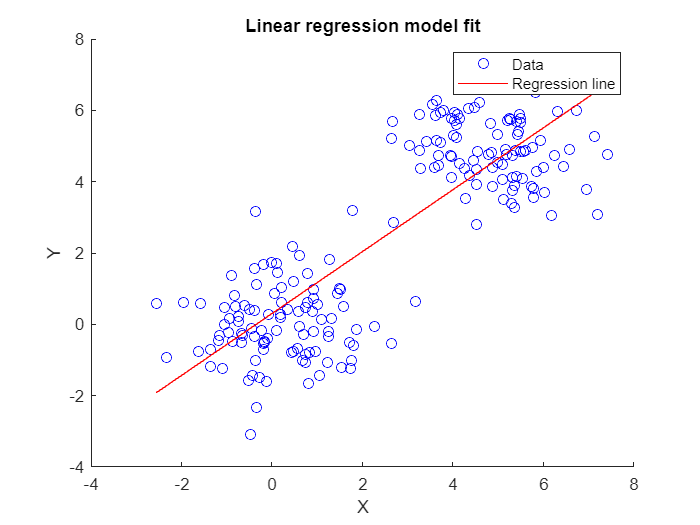

% Extract the points from 1 to 200
X = data(1:200, 1);
Y = data(1:200, 2);

% Fit a linear regression model to the data
lm = fitlm(X, Y);

% Plot the data and the regression line
figure;
scatter(X, Y, 'b');
hold on;
plot(X, lm.predict(X), 'r');
title('Linear regression model fit');
xlabel('X');
ylabel('Y');
legend('Data', 'Regression line');

% Print the regression coefficients and the R-squared value
disp(lm.Coefficients);

                   Estimate      SE       tStat       pValue  
                   ________    _______    ______    __________

    (Intercept)    0.30309     0.14459    2.0962      0.037339
    x1             0.86817     0.04058    21.394    2.2157e-53



disp("R-squared value: " + lm.Rsquared.Ordinary);

R-squared value: 0.69804
